## Importing Data:

Parallel = (readmatrix("G:\Research\Dr. Gamini Research\Data\Angle Resolved Polarized Raman\Black Phousphorus\BlackPhosphorus_4_25_2029\RawData\ParallelData.txt")).';
Cross = (readmatrix("G:\Research\Dr. Gamini Research\Data\Angle Resolved Polarized Raman\Black Phousphorus\BlackPhosphorus_4_25_2029\RawData\CrossData.txt")).';
Unpolarized = flip(readmatrix("G:\Research\Dr. Gamini Research\Data\Angle Resolved Polarized Raman\Black Phousphorus\BlackPhosphorus_4_25_2029\RawData\unpolarized.txt")).';

UnpolarizedSpectrumNormalized = mat2gray(sum([Parallel(2:end,2:end); Cross(2:end,2:end)])); % normalizing the unpolarized data

RamanShift = Unpolarized(1,:);


## **Unpolarized Spectrum:**


% removing baseline by airPLS method.

[CorrectedUnpolarizedSpectra, error]=airPLS(UnpolarizedSpectrumNormalized, 10e4,2,0.1,0.08,200);

% lorentzian function of three peaks for fitting.  

lorentzian = @(p, x) p(1) + p(2) ./ (1 + ((x-p(3))./p(4)).^2) + p(5) ./ (1 + ((x-p(6))./p(7)).^2) + p(8) ./ (1 + ((x-p(9))./p(10)).^2);

Gaussian = @(p,x) (p(1) + p(2).*exp(-((x-p(3)).^2)./(2.*(p(4).^2))) + p(5).*exp(-((x-p(6)).^2)./(2.*(p(7).^2))) + p(8).*exp(-((x-p(9)).^2)./(2.*(p(10).^2))));

Gaussian1 = @(p,x) p(1) + p(2)*exp(-((x-p(3)).^2)./(2*(p(4).^2)));

% set initial guesses for parameters

p0U = [0   ,   0.86	     ,  360.49	     ,       2.44	,0.527,	        437.59	,     2.67,	  0.99,	             464.92,	2.71];

lbU = [0,        0,     p0U(1,3)-p0U(1,4),        0,      0,     p0U(1,6)-p0U(1,7),     0,       0,     p0U(1,9)-p0U(1,10),       0];

ubU = [0.02,     1,     p0U(1,3)+p0U(1,4),        4,     1,      p0U(1,6)+p0U(1,7),     4,       1,     p0U(1,9)+p0U(1,10),     4];

lorentzianFun = @(p) lorentzian(p,RamanShift)-CorrectedUnpolarizedSpectra;

GaussianFun = @(p) Gaussian(p, RamanShift) - CorrectedUnpolarizedSpectra;


ProblemG = createOptimProblem('lsqnonlin','x0',p0U,'objective',GaussianFun,'lb',lbU,'ub',ubU);
msG = MultiStart;
[xmulti,errormulti] = run(msG,ProblemG,100);

MultiStart completed the runs from all start points. 

All 100 local solver runs converged with a positive local solver exitflag.


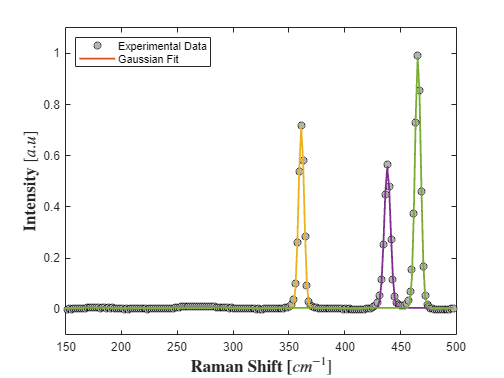



figUnpol = figure;
scatter(RamanShift, CorrectedUnpolarizedSpectra, "MarkerEdgeColor",'black','DisplayName', 'Data', "MarkerFaceColor",[0.7 0.7 0.7])
hold on
plot(RamanShift, Gaussian(xmulti, RamanShift), "LineWidth",1.5, 'DisplayName','Fit')
plot(RamanShift, Gaussian1(xmulti(1:4), RamanShift), "LineWidth",1.5)
plot(RamanShift, Gaussian1(xmulti([1,5:7]), RamanShift),"LineWidth",1.5)
plot(RamanShift, Gaussian1(xmulti([1,8:10]), RamanShift),"LineWidth",1.5)
hold off
xlabel("$\textbf{Raman Shift [$cm^{-1}]$}$", Interpreter='latex', FontSize=14, FontWeight='bold')
ylabel("$\textbf{Intensity $[a.u]$}$", Interpreter='latex', FontSize=14, FontWeight='bold')
xlim([150 500]);
ylim([-0.1 1.1]);
box on
legend("Experimental Data", 'Gaussian Fit', Location='northwest')


% xmulti contains the fitting information.

## **Substracting baseline using airPLS for all polarized spectra: **


ParallelData= Parallel(2:end, 2:end); % removing the raman shift and angles columns, as well as transposing the matrix to be used in airLPS

CrossData= Cross(2:end, 2:end);

AnglesDegs = (Parallel(2:end, 1)).' ;

AnglesRad = deg2rad(AnglesDegs);

% empty arraies for basline corrected data

correctedDataParallel = ones(size(ParallelData));

correctedDataCross = ones(size(CrossData));


sz = size(AnglesRad);

szramanshift = size(RamanShift);


% baseline substraction

for i= 1:sz(1,2)     % this loop uses 8 cores (M=8) to compute the for loop
    [xbc1,xb1]=airPLS(ParallelData(i,:), 10e4,2,0.1,0.08,200);
    correctedDataParallel(i,:) = xbc1;
    [xbc2,xb2]=airPLS(CrossData(i,:), 10e4,2,0.1,0.08,200);
    correctedDataCross(i,:) = xbc2;
end

% normalizing both configuration between 0 and 1
AllDataNormalized = mat2gray([correctedDataParallel; correctedDataCross]);

AllData = [correctedDataParallel; correctedDataCross];

 

## Plotting Normalized airPLS Baseline-Corrected Raman Sepctra :

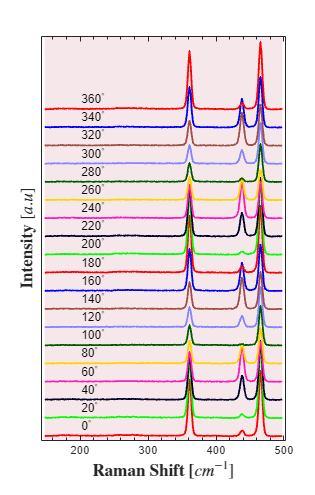



figP = figure;
area(RamanShift, ones(size(RamanShift))*5.5, BaseValue=-0.05, FaceColor=[0.6350 0.0780 0.1840], FaceAlpha=0.1, EdgeColor="none")
hold on
for i=1:19
    sep = 0.25;
    plot(RamanShift, AllDataNormalized(i,:)+(i-1)*sep, "LineWidth",1.5)
    text(200, (i*sep)-0.12, string(AnglesDegs(i)) + '^{\circ}');
   
end 
hold off
figP.Position = [0 0 350 550];
xlim([143 502]);
ylim([-0.05 5.5]);
xlabel("$\textbf{Raman Shift [$cm^{-1}]$}$", Interpreter='latex', FontSize=14, FontWeight='bold')
ylabel("$\textbf{Intensity $[a.u]$}$", Interpreter='latex', FontSize=14, FontWeight='bold')
set(gca, 'YTickLabel', [], 'YTick', [], 'XMinorTick', 'On')
ax=gca;
ax.ColorOrder = distinguishable_colors(9);

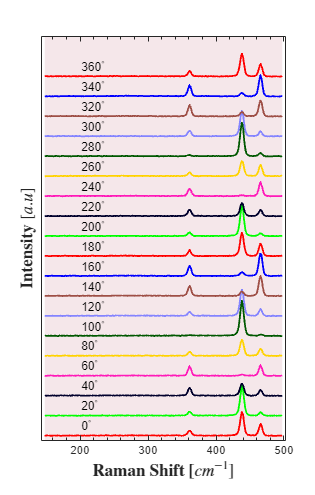



figC = figure;
area(RamanShift, ones(size(RamanShift))*5.5, BaseValue=-0.05, FaceColor=[0.6350 0.0780 0.1840], FaceAlpha=0.1, EdgeColor="none")
hold on
j=1;
for i=20:38
    sep = 0.25;
    plot(RamanShift, AllDataNormalized(i,:)+(j-1)*sep, "LineWidth",1.5)
    text(200, (j*sep)-0.14, string(AnglesDegs(j)) + '^{\circ}');
    j=j+1;
end 
hold off
figC.Position = [0 0 350 550];
xlim([143 502]);
ylim([-0.05 5]);
xlabel("$\textbf{Raman Shift [$cm^{-1}]$}$", Interpreter='latex', FontSize=14, FontWeight='bold')
ylabel("$\textbf{Intensity $[a.u]$}$", Interpreter='latex', FontSize=14, FontWeight='bold')
set(gca, 'YTickLabel', [], 'YTick', [], 'XMinorTick','On');
ax=gca;
ax.ColorOrder = distinguishable_colors(9);

## **Creating images of raw data:**

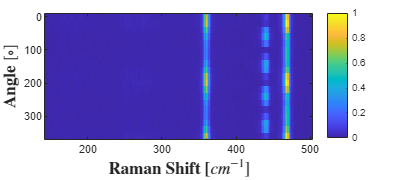

% Parallel Configuration
figPicP = figure;
 figPicP.Position = [0 0 450 200];
xax = [143 502];
yax = [min(AnglesDegs) max(AnglesDegs)];
imagesc(xax, yax, AllDataNormalized(1:sz(1,2),:));
xlabel("$\textbf{Raman Shift [$cm^{-1}]$}$", Interpreter='latex', FontSize=14, FontWeight='bold')
ylabel("$\textbf{Angle $[\circ]$}$", Interpreter='latex', FontSize=14, FontWeight='bold')
set(gca, 'XMinorTick','On');
colorbar;

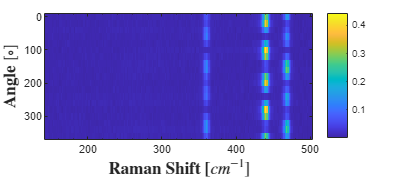


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Cross Configuration

figPicC = figure;
figPicC.Position = [0 0 450 200];
xax = [143 502];
yax = [min(AnglesDegs) max(AnglesDegs)];
imagesc(xax, yax, AllDataNormalized((1+sz(1,2)):end,:));
xlabel("$\textbf{Raman Shift [$cm^{-1}]$}$", Interpreter='latex', FontSize=14, FontWeight='bold')
ylabel("$\textbf{Angle $[\circ]$}$", Interpreter='latex', FontSize=14, FontWeight='bold')
set(gca, 'XMinorTick','On');
colorbar;

## **Fitting to Lorentzian or Gaussian Function All Raman Spectra: **

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


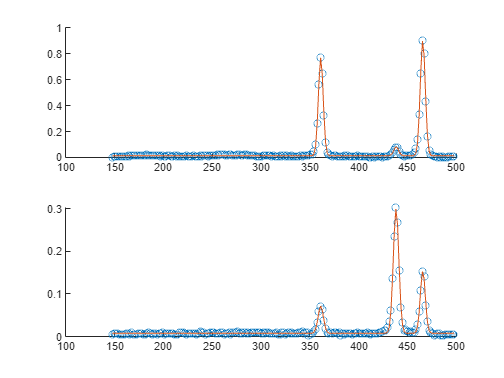

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


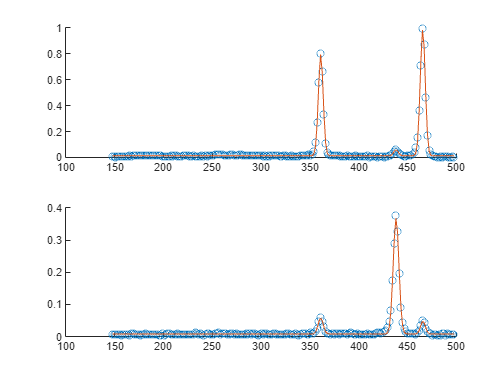

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


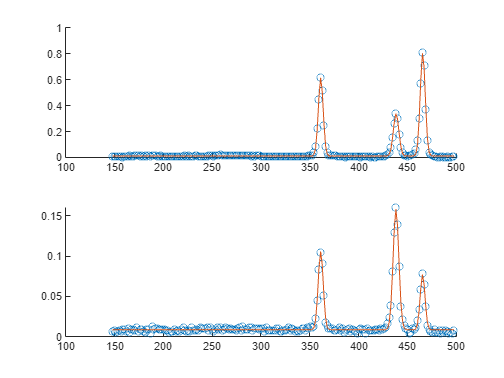

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


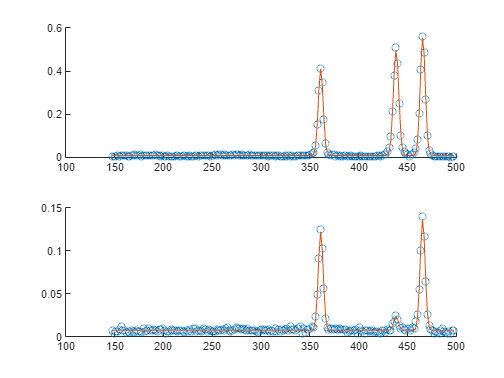

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


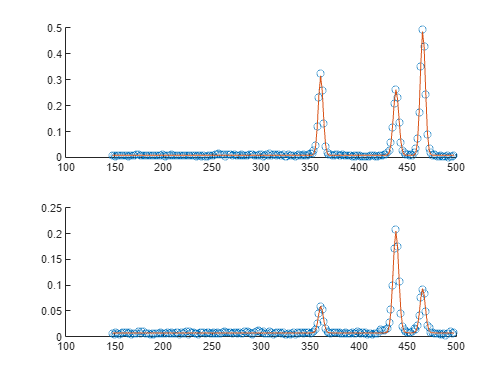

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


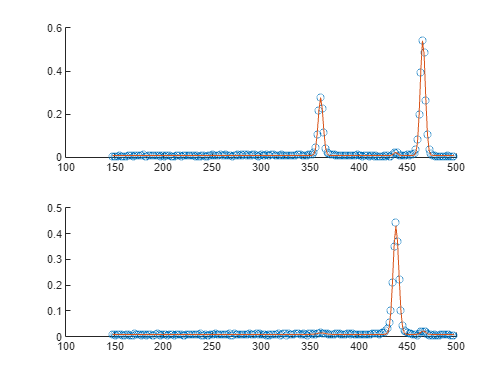

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


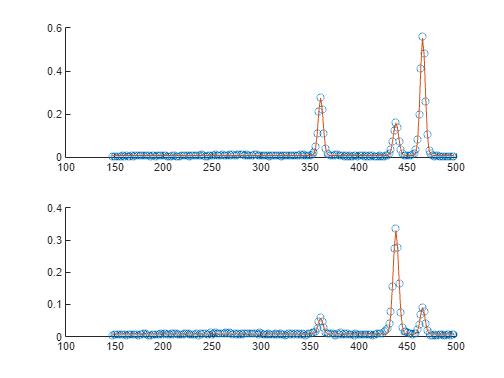

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


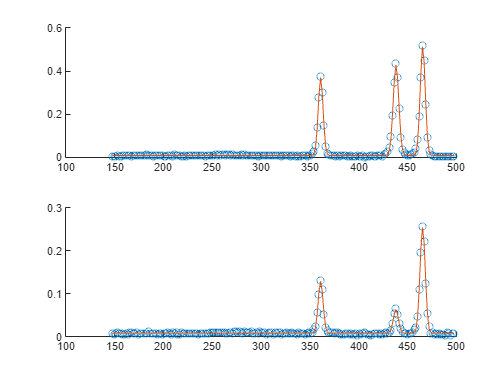

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


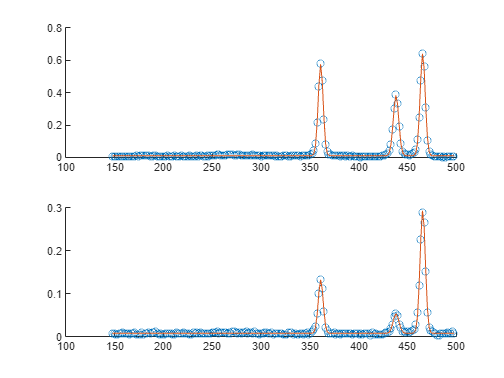

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


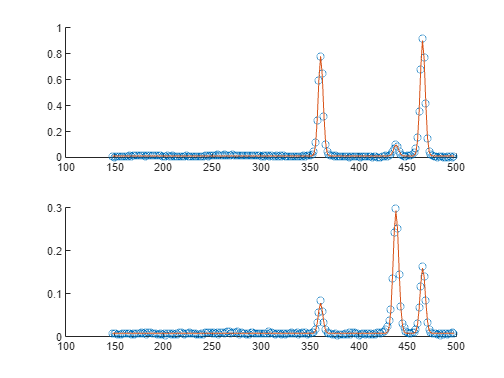

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


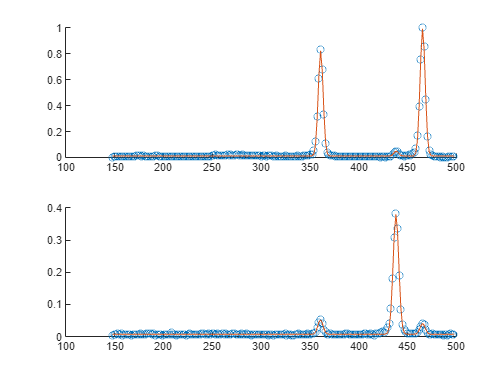

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


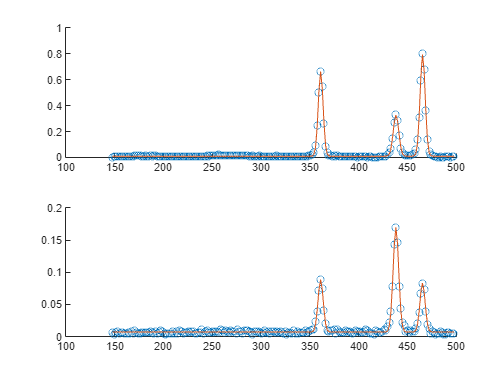

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


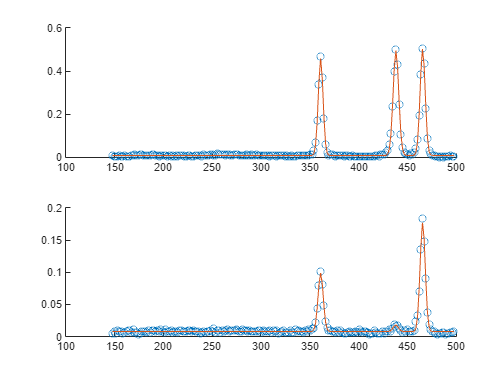

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


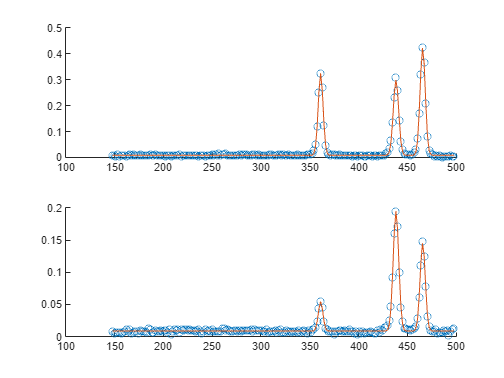

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


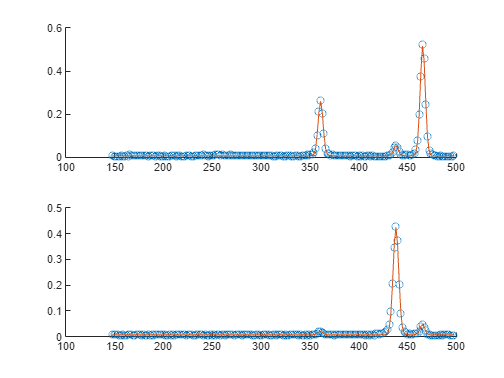

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


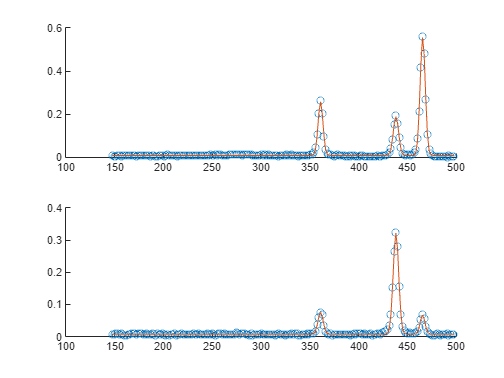

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


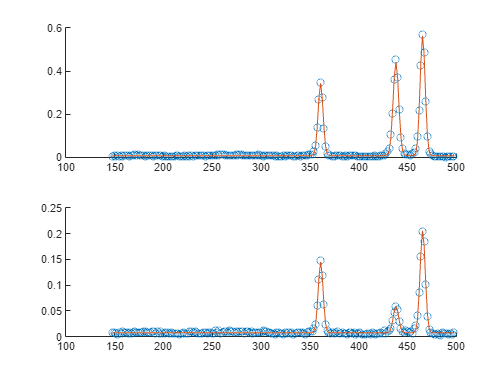

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


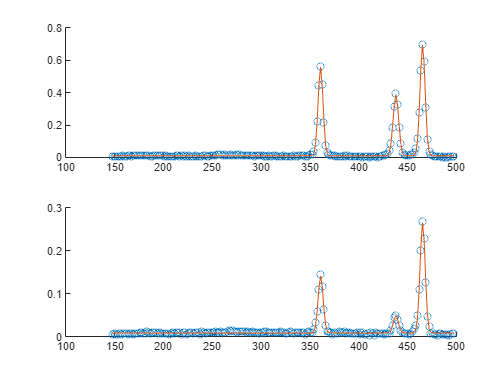

MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


MultiStart completed the runs from all start points. 

All 500 local solver runs converged with a positive local solver exitflag.


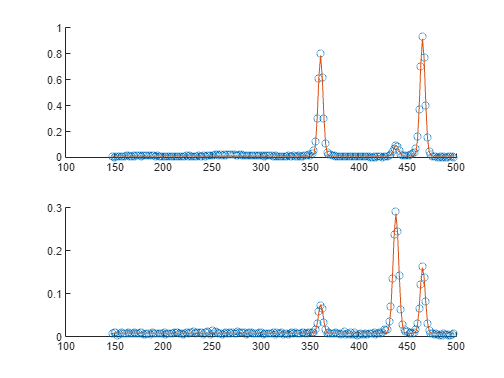

% fitting BP spectra to the sum of three lorentzian functions
lorentzian = @(p, x) p(1) + p(2) ./ (1 + ((x-p(3))/p(4)).^2) + p(5) ./ (1 + ((x-p(6))/p(7)).^2) + p(8) ./ (1 + ((x-p(9))/p(10)).^2);

lorentzian1 = @(p,x)p(1)+p(2)./(1+((x-p(3))/p(4)).^2);


Gaussian = @(p,x) p(1) + p(2)*exp(-((x-p(3)).^2)./(2*(p(4).^2))) + p(5)*exp(-((x-p(6)).^2)./(2*(p(7).^2))) + p(8)*exp(-((x-p(9)).^2)./(2*(p(10).^2)));

Gaussian1 = @(p,x) p(1) + p(2)*exp(-((x-p(3)).^2)./(2*(p(4).^2)));
% set initial guesses for parameters

ymax = max(AllDataNormalized, [], "all");
ymin = min(AllDataNormalized,[], "all");
dmaxmin  = abs(ymax - ymin);

p0 = [0   ,   0.8	     ,  360.49	     ,       2.44	,0.5,	        437.59	,     2.67,	  0.5,	             464.92,	2.71];

lb = [ymin,        ymin,     p0U(1,3)-p0U(1,4),        0,      0,     p0U(1,6)-p0U(1,7),     0,       0,     p0U(1,9)-p0U(1,10),       0];

ub = [ymax,     ymax,     p0U(1,3)+p0U(1,4),        4,     ymax,      p0U(1,6)+p0U(1,7),     4,       ymax,     p0U(1,9)+p0U(1,10),     4];


PeaksOffsetParallel = ones(sz(1,2),1);
PeaksOffsetCross = ones(sz(1,2),1);

[Peak1HighetParallel, Peak2HighetParallel, Peak3HighetParallel] = deal(ones(sz(1,2),1));
[Peak1HighetCross, Peak2HighetCross, Peak3HighetCross] = deal(ones(sz(1,2),1));

[Peak1CenterParallel, Peak2CenterParallel, Peak3CenterParallel] = deal(ones(sz(1,2),1));
[Peak1CenterCross, Peak2CenterCross, Peak3CenterCross] = deal(ones(sz(1,2),1));

[Peak1FWHMParallel, Peak2FWHMParallel, Peak3FWHMParallel] = deal(ones(sz(1,2),1));
[Peak1FWHMCross, Peak2FWHMCross, Peak3FWHMCross] = deal(ones(sz(1,2),1));

FittedData = ones([(2*sz(1,2)) szramanshift(1,2)]);

tic
for i=1:sz(1,2)
    DataP = AllDataNormalized(i,:);
    lorentzianFunP = @(p) Gaussian(p,RamanShift)-DataP;
    ProblemP = createOptimProblem('lsqnonlin','x0',p0,'objective',lorentzianFunP,'lb',lb,'ub',ub);
    msP = MultiStart;
    [xmultiP,errormultiP] = run(msP,ProblemP,500);

    PeaksOffsetParallel(i) = xmultiP(1);
    [Peak1HighetParallel(i), Peak2HighetParallel(i), Peak3HighetParallel(i)] = deal(xmultiP(2), xmultiP(5), xmultiP(8));
    [Peak1CenterParallel(i), Peak2CenterParallel(i), Peak3CenterParallel(i)] = deal(xmultiP(3), xmultiP(6), xmultiP(9));
    [Peak1FWHMParallel(i), Peak2FWHMParallel(i), Peak3FWHMParallel(i)] = deal(2*sqrt(2*log(2))*xmultiP(4), 2*sqrt(2*log(2))*xmultiP(7), 2*sqrt(2*log(2))*xmultiP(10));



    FittedData(i,:) = Gaussian(xmultiP, RamanShift);

    DataC = AllDataNormalized(i+sz(1,2),:);
    lorentzianFunC = @(p) Gaussian(p,RamanShift)-DataC;
    ProblemC = createOptimProblem('lsqnonlin','x0',p0,'objective',lorentzianFunC,'lb',lb,'ub',ub);
    msC = MultiStart;
    [xmultiC,errormultiC] = run(msC,ProblemC,500);

    PeaksOffsetCross(i) = xmultiC(1);
    [Peak1HighetCross(i), Peak2HighetCross(i), Peak3HighetCross(i)] = deal(xmultiC(2), xmultiC(5), xmultiC(8));
    [Peak1CenterCross(i), Peak2CenterCross(i), Peak3CenterCross(i)] = deal(xmultiC(3), xmultiC(6), xmultiC(9));
    [Peak1FWHMCross(i), Peak2FWHMCross(i), Peak3FWHMCross(i)] = deal(2*sqrt(2*log(2))*xmultiC(4), 2*sqrt(2*log(2))*xmultiC(7), 2*sqrt(2*log(2))*xmultiC(10));

    FittedData(i+sz(1,2),:)=Gaussian(xmultiC, RamanShift);

    fig = figure;
    ax17= subplot(2,1,1);
    scatter(RamanShift, DataP);
    hold on;
    plot(RamanShift, Gaussian(xmultiP, RamanShift));
    hold off;
    ax27 = subplot(2,1,2);
    scatter(RamanShift, DataC);
    hold on ;
    plot(RamanShift, Gaussian(xmultiC, RamanShift));
    hold off;

end

t = toc

t = 171.9575

## Plotting APRS Peaks without Fitting: 

Parallel-configuration peaks:

AnglesRad = (0:20:360)*(pi/180);
anglesmore = (0:pi/100:2*pi);

c1 = [0.6350 0.0780 0.1840].*0.1 + [1 1 1].*(1-0.1)

c1 =     0.9635    0.9078    0.9184


figFitP = figure(Color='White');
figFitP.Position = [200 200 1000 500]

figFitP =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [1 1 1]
    Position: [200 200 1000 500]
       Units: 'pixels'

  Show all properties


ax1P =subplot(2,3,1);
polarplot(AnglesRad, Peak1HighetParallel, 'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])

ax2P = subplot(2,3,2);
polarplot(AnglesRad, Peak2HighetParallel, 'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])

ax3P = subplot(2,3,3);
polarplot(AnglesRad, Peak3HighetParallel, 'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])


Perpendicular-configuration peaks:

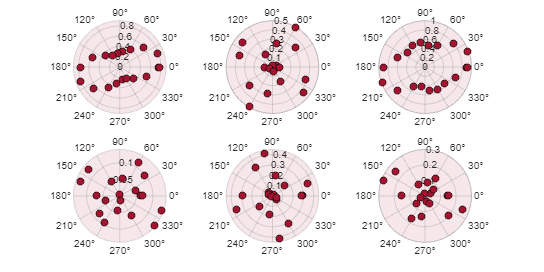

ax1C =subplot(2,3,4);
polarplot(AnglesRad, Peak1HighetCross,'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])

ax2C = subplot(2,3,5);
polarplot(AnglesRad, Peak2HighetCross, 'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])


ax3C = subplot(2,3,6);
polarplot(AnglesRad, Peak3HighetCross, 'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])

set(subplot(2,3,1),'Color',c1)
set(subplot(2,3,2),'Color',c1)
set(subplot(2,3,3),'Color',c1)
set(subplot(2,3,4),'Color',c1)
set(subplot(2,3,5),'Color',c1)
set(subplot(2,3,6),'Color',c1)

## **Fitting APRS Peaks of BP:**

Parallel configuration fitting functions for BP modes:

$I_{\textrm{Ag}}^{||} =a^2 *{\sin \left(\theta \right)}^4 +2*a*c*{\sin \left(\theta \right)}^2 {*\cos \left(\theta \right)}^2 *\cos \left(\phi_{\textrm{ac}} \right)+{c^2 *\cos \left(\theta \right)}^4$;

$I_{B_{2g} }^{||} ={{\left(f*\sin \left(2\theta \right)\right)}^2 }$;

Cross configuration fitting functions for BP modes:

$I_{\textrm{Ag}}^{\bot } =\left({\;a}^2 -2*a*c*\cos \left(\phi_{\textrm{ac}} \right)+c^2 \right)*{\sin \left(\theta \right)}^2 {*\cos \left(\theta \right)}^2$;

$I_{B_{2g} }^{\bot } ={\left(f*\cos \left(2\theta \right)\right)}^2$;

fParallel_Ag = @(p, theta)   (1/8).*(3.*(p(1).^2) + 3.*(p(2).^2) + 2.*p(1).*p(2).*cos(p(3))-p(1).*p(2).*cos(p(3) + 4.*p(4) - 4.*theta)-4.*((p(1).^2)-(p(2).^2)).*cos(2.*(p(4)-theta)) +((p(1).^2)+(p(2).^2)).*cos(4.*(p(4)-theta))- p(1).*p(2).*cos(p(3)- 4.*p(4)+4.*theta));

fPerpendicular_Ag = @(p, theta) (1/4).*((p(1).^2) + (p(2).^2) - 2.*p(1).*p(2).*cos(p(3))).*((sin(2.*(p(4)-theta))).^2);

fParallel_B2g = @(p, theta) (p(1).^2).*(sin(2.*(p(2)-theta))).^2;

fPerpendicular_B2g = @(p, theta) (p(1).^2).*(cos(2.*(p(2)-theta))).^2;



p0Ag = [0 0.5 0.5 0 ];

lAg = [-1 -1 0 0 ];

uAg = [1 1 pi/2 2*pi];

p0B = [0 0];

lB = [-1 0 ];

uB = [1 2*pi ];

fAgP1 = @(p) fParallel_Ag(p,AnglesRad)-(Peak1HighetParallel.');
ProblemP1 = createOptimProblem('lsqnonlin','x0',p0Ag,'objective',fAgP1,'lb',lAg,'ub',uAg);
msP1 = MultiStart("UseParallel",true);
[xmultiP1,errormultiP1] = run(msP1,ProblemP1,100);

MultiStart completed the runs from all start points. 

All 100 local solver runs converged with a positive local solver exitflag.



fAgC1 = @(p) fPerpendicular_Ag(p,AnglesRad)-(Peak1HighetCross.');
ProblemC1 = createOptimProblem('lsqnonlin','x0',p0Ag,'objective',fAgC1,'lb',lAg,'ub',uAg);
msC1 = MultiStart("UseParallel",true);
[xmultiC1,errormultiC1] = run(msC1,ProblemC1,100);

MultiStart completed the runs from all start points. 

All 100 local solver runs converged with a positive local solver exitflag.




fB2gP = @(p) fParallel_B2g(p,AnglesRad)-(Peak2HighetParallel.');
ProblemPB2g = createOptimProblem('lsqnonlin','x0',p0B,'objective',fB2gP,'lb',lB,'ub',uB);
msPB2g = MultiStart("UseParallel",true);
[xmultiPB2g,errormultiPB2g] = run(msPB2g,ProblemPB2g,100);

MultiStart completed the runs from all start points. 

All 100 local solver runs converged with a positive local solver exitflag.




fB2gC = @(p) fPerpendicular_B2g(p,AnglesRad)-(Peak2HighetCross.');
ProblemCB2g = createOptimProblem('lsqnonlin','x0',p0B,'objective',fB2gC,'lb',lB,'ub',uB);
msCB2g = MultiStart("UseParallel",true);
[xmultiCB2g,errormultiCB2g] = run(msCB2g,ProblemCB2g,100);

MultiStart completed the runs from all start points. 

All 100 local solver runs converged with a positive local solver exitflag.





fAgP2 = @(p) fParallel_Ag(p,AnglesRad)-(Peak3HighetParallel.');
ProblemP2 = createOptimProblem('lsqnonlin','x0',p0Ag,'objective',fAgP2,'lb',lAg,'ub',uAg);
msP2 = MultiStart("UseParallel",true);
[xmultiP2,errormultiP2] = run(msP2,ProblemP2,100);

MultiStart completed the runs from all start points. 

All 100 local solver runs converged with a positive local solver exitflag.



fAgC2 = @(p) fPerpendicular_Ag(p,AnglesRad)-(Peak3HighetCross.');
ProblemC2 = createOptimProblem('lsqnonlin','x0',p0Ag,'objective',fAgC2,'lb',lAg,'ub',uAg);
msC2 = MultiStart("UseParallel",true);
[xmultiC2,errormultiC2] = run(msC2,ProblemC2,100);

MultiStart completed the runs from all start points. 

All 100 local solver runs converged with a positive local solver exitflag.


## Plotting ARPR Peaks with fitting:

Parallel-configuration peaks:

c1 = [0.6350 0.0780 0.1840].*0.1 + [1 1 1].*(1-0.1)

c1 =     0.9635    0.9078    0.9184


figFitP = figure(Color='White');
figFitP.Position = [200 200 1000 500]

figFitP =   Figure (32) with properties:

      Number: 32
        Name: ''
       Color: [1 1 1]
    Position: [200 200 1000 500]
       Units: 'pixels'

  Show all properties


ax1 =subplot(2,3,1);
polarplot(AnglesRad, Peak1HighetParallel, 'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])
hold on 
polarplot(anglesmore, fParallel_Ag(xmultiP1, anglesmore), 'black', LineWidth=1.5)
hold off

ax2 = subplot(2,3,2);
polarplot(AnglesRad, Peak2HighetParallel, 'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])
hold on 
polarplot(anglesmore, fParallel_B2g(xmultiPB2g, anglesmore), 'black', LineWidth=1.5)
hold off
ax3 = subplot(2,3,3);
polarplot(AnglesRad, Peak3HighetParallel, 'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])
hold on 
polarplot(anglesmore, fParallel_Ag(xmultiP2, anglesmore), 'black', LineWidth=1.5)
hold off

Perpendicular-configuration peaks:

ax4 =subplot(2,3,4);
polarplot(AnglesRad, Peak1HighetCross,'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])
hold on 
polarplot(anglesmore, fPerpendicular_Ag(xmultiC1, anglesmore), 'black', LineWidth=1.5)
hold off

ax5 = subplot(2,3,5);
polarplot(AnglesRad, Peak2HighetCross, 'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])
hold on 
polarplot(anglesmore, fPerpendicular_B2g(xmultiCB2g, anglesmore), 'black', LineWidth=1.5)
get(gca)

                        ALim: [0 1]
                    ALimMode: 'auto'
                  AlphaScale: 'linear'
                    Alphamap: [0 0.0159 0.0317 0.0476 0.0635 0.0794 0.0952 0.1111 0.1270 0.1429 0.1587 0.1746 0.1905 0.2063 0.2222 0.2381 0.2540 0.2698 0.2857 0.3016 0.3175 0.3333 0.3492 0.3651 0.3810 0.3968 0.4127 0.4286 0.4444 0.4603 … ] (1×64 double)
                BeingDeleted: off
                         Box: on
                  BusyAction: 'queue'
               ButtonDownFcn: ''
                        CLim: [0 1]
                    CLimMode: 'auto'
                    Children: [2×1 Line]
                    Clipping: on
                       Color: [1 1 1]
                  ColorOrder: [7×3 double]
             ColorOrderIndex: 3
                  ColorScale: 'linear'
                    Colormap: [256×3 double]
                 ContextMenu: [0×0 GraphicsPlaceholder]
                   CreateFcn: ''
                CurrentPoint: [3.4062 2.8274]
                 

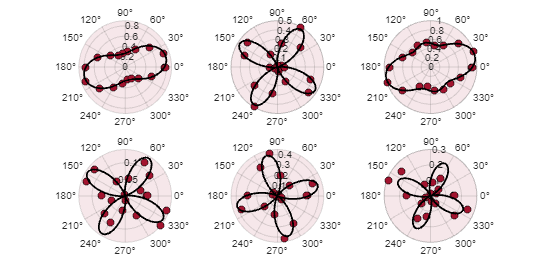

hold off

ax6 = subplot(2,3,6);
polarplot(AnglesRad, Peak3HighetCross, 'ko',"MarkerEdgeColor",'black', "MarkerFaceColor", [0.6350 0.0780 0.1840])
hold on 
polarplot(anglesmore, fPerpendicular_Ag(xmultiC2, anglesmore), 'black', LineWidth=1.5)
hold off
set(subplot(2,3,1),'Color',c1)
set(subplot(2,3,2),'Color',c1)
set(subplot(2,3,3),'Color',c1)
set(subplot(2,3,4),'Color',c1)
set(subplot(2,3,5),'Color',c1)
set(subplot(2,3,6),'Color',c1)